# 案例：超好看的淡色系

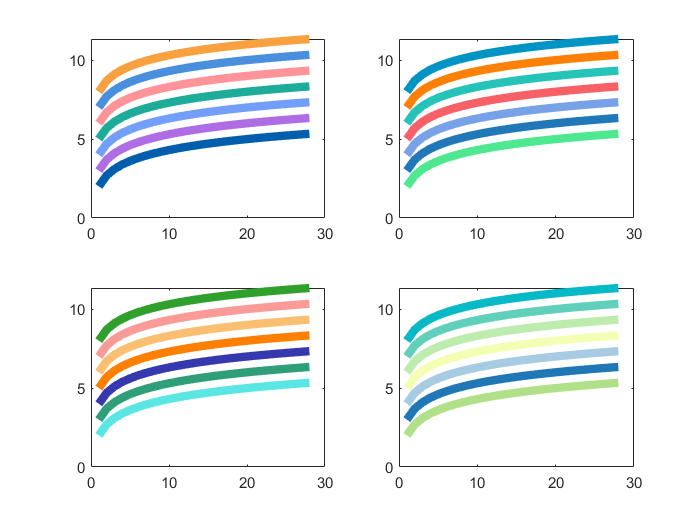

clear;clc;close all;
cString = {'#005EAD', '#AF6DE5', '#719FFB', '#1CAC99', '#FE9499', '#4A8FDE', '#F8A13E', ...
           '#4DE890', '#2178B8', '#77A2E8', '#F86067', '#26C4B8', '#FE8006', '#0094C5', ...
           '#5AE7E4', '#2E9F79', '#3638AE', '#FF7F00', '#FBBF72', '#FA9B97', '#30A02D', ...
           '#B0E188', '#2077B5', '#A8CBE4', '#F5FFB3', '#BEECAF', '#61D0BA', '#05B9C7'};
count = length(cString);
x = 1:count;
y = log(x) + 1;
c = zeros(count, 3);
for i = 1:count
    c(i, :) = String2Color(cString{i});
end
% 每一行就是一种颜色
% c_map = c/256;
c_map =  [0.00, 0.36, 0.67
          0.68, 0.42, 0.89
          0.44, 0.62, 0.98
          0.10, 0.67, 0.59
          0.99, 0.57, 0.59
          0.28, 0.55, 0.86
          0.96, 0.62, 0.24
          0.30, 0.90, 0.56
          0.12, 0.46, 0.71
          0.46, 0.63, 0.90
          0.96, 0.37, 0.40
          0.14, 0.76, 0.71
          0.99, 0.50, 0.02
          0.00, 0.57, 0.76
          0.35, 0.90, 0.89
          0.17, 0.62, 0.47
          0.21, 0.21, 0.67
          0.99, 0.49, 0.00
          0.98, 0.74, 0.44
          0.97, 0.60, 0.58
          0.18, 0.62, 0.17
          0.68, 0.87, 0.53
          0.12, 0.46, 0.70
          0.65, 0.79, 0.89
          0.95, 0.99, 0.69
          0.74, 0.92, 0.68
          0.37, 0.81, 0.72
          0.01, 0.72, 0.77];
figure;
for m = 1:4
    subplot(2, 2, m);
    for i = 1:7
        plot(x, y + i, 'color', cString{7*m - 7 + i}, 'LineWidth', 5);
        hold on
    end
    hold off
end

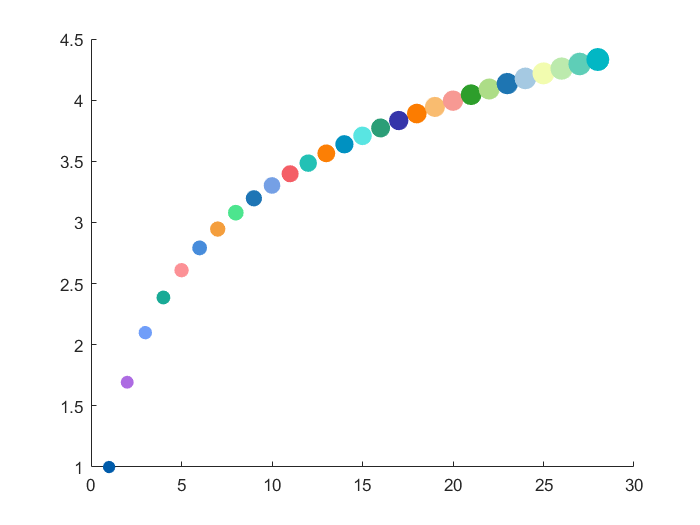

figure;
colormap(c_map);
scatter(x, y, 5*x + 50, x, 'filled');

function c = String2Color(str)
clist = '0123456789ABCDEF';
nums = zeros(1, 6);
for i = 1:6
    nums(i) = find(str(i + 1) == clist);
end
c = zeros(1, 3);
for i = 1:3
    c(i) = 16 * (nums(2*i-1) - 1) + (nums(2*i) - 1);
end
end